Quick interactive tutorial on using Daubechies' wavelets for eigenvalue problems. 

**[Example]**

Assumes familiarity with all other notebooks in folder. 

Solves for eigenvalues of a 1D Particle in a Box. 

- Goes upto 3 levels of resolution.

- Extracts theoretical eigenfunction from the peaks of the numerical eigenfunction

- Feeds it back into hamiltonian for eigenvalue


$$\frac{d^2f(x)}{dx^2} + V(x)  { = Ef(x)$$


V(x) = 0 for x in [1,8], 100 elsewhere


$$E_{min} = (\pi/7)^2$$


[ws,x] = wpfun('db5', 1, 10); W = ws(2,:); S = ws(1,:);

You need to upsample the lower resolution wavelets for calculating integrals which involve higher resolution wavelets.

%desiredPointCount = 9218 * 2 * 2 *2; %for PREC=10
basis = [];

%phi k=0 n=0
s00 = S;
for i = 1:3
    s00 = upsample(s00, 2); 
    s00(s00 == 0) = NaN;
   [s00,~] = fillmissing(s00,'linear');
end
basis(1,:) = s00;

%psi k=0 n=0
w00 = W;
for i = 1:3
    w00 = upsample(w00, 2); 
    w00(w00 == 0) = NaN;
   [w00,~] = fillmissing(w00,'linear');
end
basis(2,:) = w00;

%psi k=1 n=0:9
k = 1;
for n = 0:9
   [w,~] = DT(W, x, k, n);
   for i=1:2
    w = upsample(w, 2);
    w(w == 0) = NaN;
   [w,~] = fillmissing(w, 'linear');
   end
   basis(n+3,:) = w;
end

%psi k=2 n=0:27
k=2;
for n = 0:27
   [w,~] = DT(W, x, k, n);
   for i=1:1
    w = upsample(w, 2);
    w(w == 0) = NaN;
   [w,~] = fillmissing(w, 'linear');
   end
   basis(n+13,:) = w;  
end

%psi k=3 n=0:63
k=3;
for n = 0:63
   [basis(n+41,:),~] = DT(W, x, k, n);   
end

[~, x] = DT(S, x, k, n);
sz = size(basis); sz = sz(1);

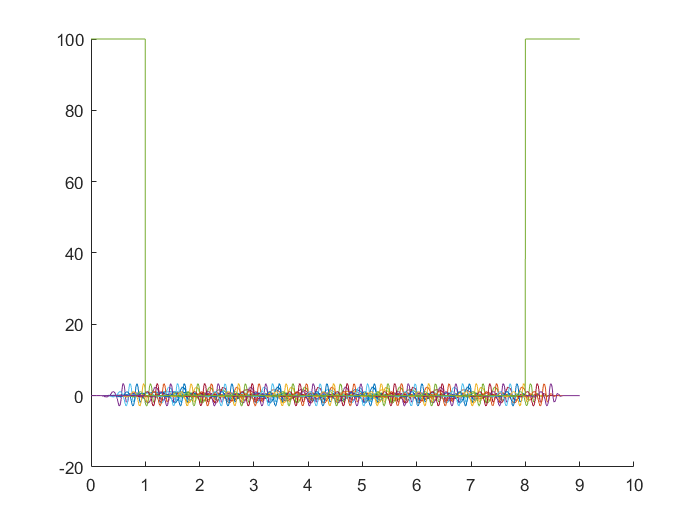

% % inspect basis elements
j=1; Vplot = zeros(size(x));
for i=x
    if i < 1
        Vplot(j) = 100;
    end
    if i > 8
        Vplot(j) = 100;
    end
    j = j+1;
end
clf
hold on
for i = 1:104
    figure(1)
    plot(x, basis(i,:))
    plot(x, Vplot)
end
hold off

% %% % inspect orthonormality of basis elements
% CHK = zeros([40 40]);
% for i = 1:40
%     for j = i:40
%         CHK(i,j) = trapz(basis(i,:) .* basis(j,:)) * x(2);
%     end
% end
% CHK = CHK + CHK' - diag(diag(CHK)); CHK

H = zeros([sz sz]); T = zeros([sz sz]); V = zeros([sz sz]);
basisd = singlediff(basis,x);
basisdd = doublediff(basis, x);

for i = 1:sz
    for j = i:sz
        T(i, j) = -0.5 * trapz(basisd(i,:) .* basisd(j,:)) * x(2);
        V(i, j) = trapz(basis(i,:) .* Vplot .* basis(j,:)) * x(2);
    end
end
H = T + V;
H = H + H' - diag(diag(H)); 
[v, d] = eig(H); 


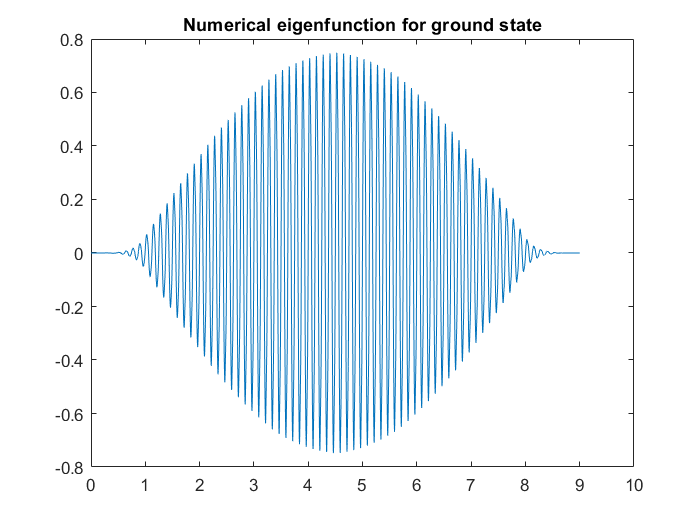

f =(v(:,1)' * basis);
figure(2)
plot(x,f)
title("Numerical eigenfunction for ground state")

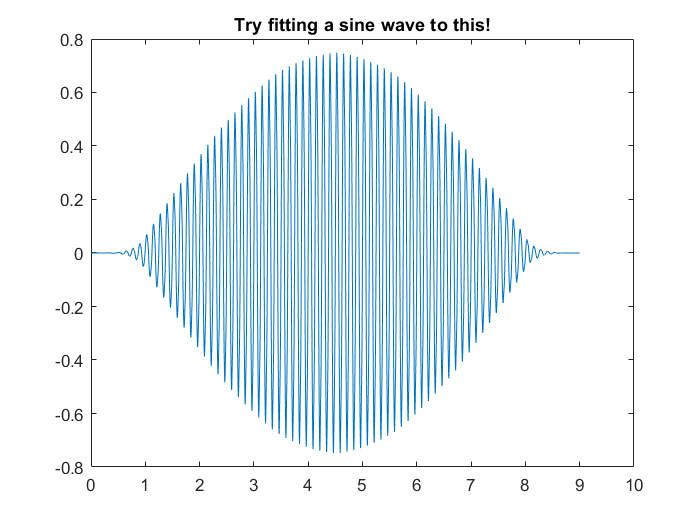

[pks, locs] = findpeaks(f);
fcg = zeros(size(f));
fcg(locs) = f(locs);
fcg(fcg==0) = NaN;
[fcg,~] = fillmissing(fcg, 'linear');
title("Try fitting a sine wave to this!");

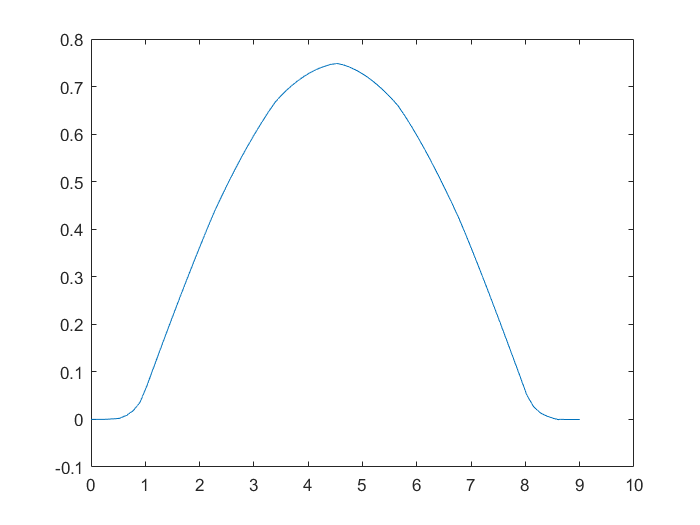

figure(3)
plot(x,fcg)

fprintf("Numerical: %f" , mean(doublediff(fcg,x) / fcg));

Numerical: -0.172144

fprintf("Theoretical: %f" , (pi/7)^2);

Theoretical: 0.201420

% % % % for inspecting eigenvalues obtained from curve joining extracted peaks

% for i = 1:sz
% f =(v(:,i)' * basis);
% [pks, locs] = findpeaks(f);
% fc = zeros(size(f));
% fc(locs) = f(locs);
% fc(fc==0) = NaN;
% [fc,~] = fillmissing(fc, 'linear');
% Hfc = -0.5 * doublediff(fc,x)  + ((x-4.5).^2)/2 .* fc;
% ec(i) = mean(Hfc./fc);
% end
% plot(1:sz, ec)

function [DTw, DTx] = DT(w,x,k,n)   
    %keep n <= (2K - 1)(2^k - 1)
    DTw = w;
    DTx = x+n;
    
    DTw = 2^(k/2)*DTw;
    DTx = DTx/(2^k);
    
    newxstep = DTx(2) - DTx(1);
    Lpad = round(DTx(1) / newxstep);
    
    DTx = wextend('1', 'asymw', DTx, length(DTx)*(2^k - 1), 'r');
    
    DTw = [DTw , zeros(1,(length(DTx) - length(DTw)))];
    DTw = circshift(DTw, Lpad); DTw(1:Lpad) = zeros(1, Lpad);   
    DTx = wextend('1', 'asymw', DTx, Lpad, 'l');
    
    DTx = DTx(1:length(DTw));
    
end

function [wd, xd] = singlediff(w, x)
    wd = gradient(w)/(x(2) - x(1));
    xd = x;
end

function [wdd, xdd] = doublediff(w, x)
    wd = gradient(w)/(x(2) - x(1));
    wdd = gradient(wd)/(x(2) - x(1));
    xdd = x;
end
